Kattints az út rajzolásához! Nyomj ENTER-t a záráshoz.
Számolás: Pálya generálás...


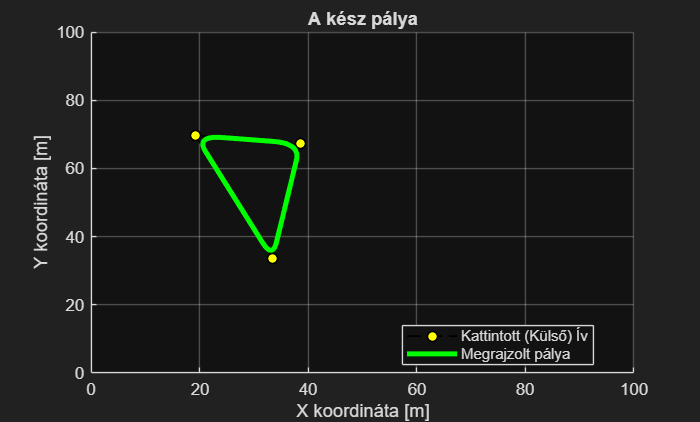

%% ============================================================
%  MAIN SCRIPT
%  ------------------------------------------------------------
%  Project name   : Tube MPC optimization with neural network
%  Author         : Bene Ádám
%  Date           : 2026.04.28.
%  Description    : Main execution script that calls the
%                   required submodules and processing steps.
%
%  Note           : Run this file directly.
%% ============================================================

% reference path define for the controller
run("path_define.mlx")

=== 2. FÁZIS: CasADi MPC Szimuláció és Adatgyűjtés ===
CasADi szimuláció fut... (az IPOPT megoldó dolgozik)
      solver  :   t_proc      (avg)   t_wall      (avg)    n_eval
       nlp_f  |        0 (       0)  24.00us (  2.40us)        10
       nlp_g  |        0 (       0)  63.00us (  6.30us)        10
  nlp_grad_f  |        0 (       0)  29.00us (  2.64us)        11
  nlp_hess_l  |        0 (       0)  19.00us (  2.11us)         9
   nlp_jac_g  |        0 (       0)  33.00us (  3.00us)        11
       total  | 876.00ms (876.00ms) 875.42ms (875.42ms)         1
      solver  :   t_proc      (avg)   t_wall      (avg)    n_eval
       nlp_f  |        0 (       0)  27.00us (  2.70us)        10
       nlp_g  |   1.00ms (100.00us)  61.00us (  6.10us)        10
  nlp_grad_f  |        0 (       0)  34.00us (  3.09us)        11
  nlp_hess_l  |        0 (       0)  18.00us (  2.00us)         9
   nlp_jac_g  |        0 (       0)  35.00us (  3.18us)        11
       total  |  20.00ms ( 20.00ms

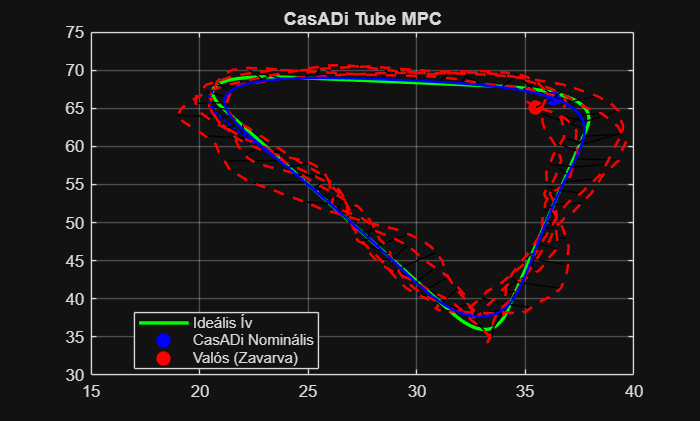


% run tube MPC for previously defined reference path
run("tube_mpc.mlx")

=== Neurális Háló Tanítása Indul ===


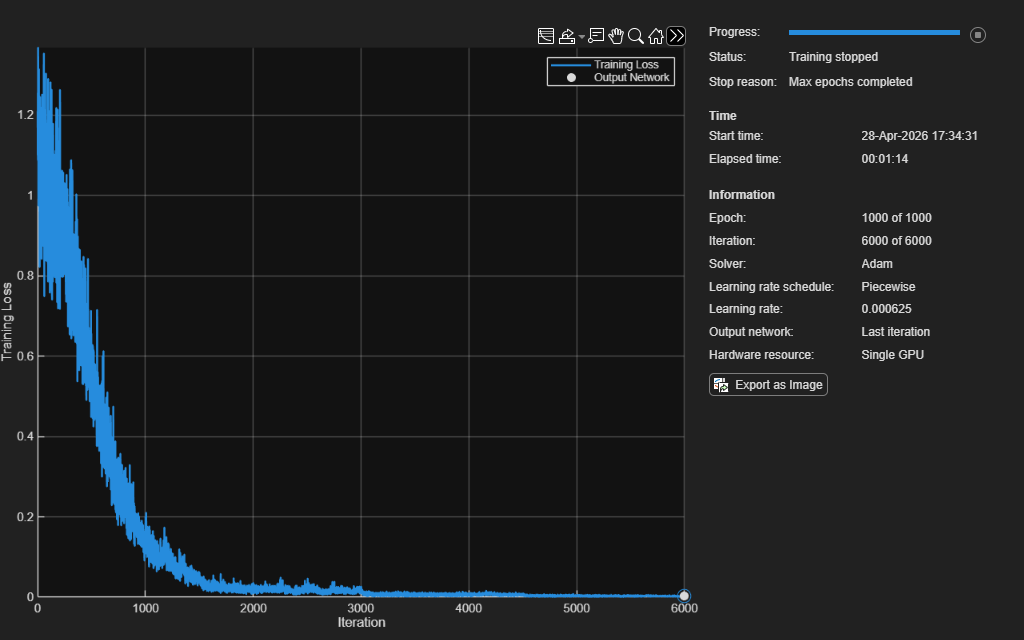

=== TANÍTÁS BEFEJEZŐDÖTT! A "net" nevű objektum elkészült. ===
--- Tesztelés az első időlépésen ---
Valós maradék hiba (a szimulációdból):
         0         0    0.1888   -0.5059

Neurális háló által becsült hiba:
   -0.0000   -0.0000    0.1901   -0.4439




% train the NN from the offline data of the previous simulation
run("train_nn.mlx")